## **Kobylański Przemysław, 297253**

## **Metodu numeryczne - projekt 1**

**1.1**. Zmienić  zapis z dziesiętnego na ósemkowy i szesnastkowy:

a) 16

b) 157

c) 2044

A=[16,157,2044];
hex=dec2base(A,16);
oct=dec2base(A,8);

disp("Zapis szesnastkowy")

Zapis szesnastkowy


disp(hex)

010
09D
7FC


disp("Zapis ósemkowy")

Zapis ósemkowy


disp (oct)

0020
0235
3774


**1.2**. Przedstawić liczbę −245.25 w zapisie stałopozycyjnym, a następnie zmiennnopozycyjnym przy założeniu, że bazą systemu jest liczba 2. Ile wynosi minimalna liczba bitów potrzebna do przechowania tej liczby w pamięci?

x = -245.25;

**1.3** Wartość popełnianego błędu zaokrąglenia jest limitowana dostępną dla danej maszyny wartością precyzji ε. 

Stała ε maszyny jest to najmniejsza liczba nieujemna ε, taka że 1 + ε != 1. Im mniejsza wartość ε tym większa względna precyzja obliczeń. Należy napisać skrypt Matlaba wyznaczający precyzję maszynową wykonywanych obliczeń.

%iteracyjne obliczenie precyzji
precision = 1;
while 1 + precision > 1
    precision = precision / 2;
end
%pomnożenie x2 ponieważ po wyjściu z pętli precyzja jest 2x mniejsza niż
%faktyczna
precision = precision * 2;
disp(['Precyzja maszynowa: ', num2str(precision)]);

Precyzja maszynowa: 2.2204e-16


**1.4**. Rozwinięcie funkcji sin(x) w szereg Maclaurina ma postać:

                            sin(x) = x − (x^`3)/3!+(x^5)/5!-...`

Dla małych wartości zmiennej x (x < 1) można aproksymować wartość funkcji sin(x) ≈ x (obcięcie rozwinięcia w szereg do pierwszego wyrazu). Należy napisać skrypt Matlaba rysujący wykres błędu względnego i bezwzględnego popełnianego podczas takiej aproksymacji w zakresie x ∈ [−0.3, 0.3] przy założeniu, że bierzemy pod uwagę odpowiednio pierwsze 1, 2 i 3 człony rozwinięcia funkcji w szereg

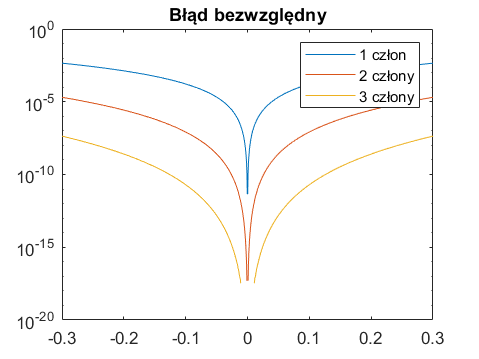

% generowanie wektora wartości zmiennej x
x = linspace(-0.3, 0.3, 1000); 
value = sin(x); % wartość dokładna
first = x; % pierwszy wyraz szeregu Maclaurina
second = x - (x.^3)./factorial(3); % dwa pierwsze wyrazy
third = x - (x.^3)./factorial(3) + (x.^5)./factorial(5); % trzy pierwsze wyrazy
absoluteError1 = abs(value - first); % błąd bezwzględny 1
relativeError1 =absoluteError1./abs(value); % błąd względny 1
absoluteError2 = abs(value - second); % błąd bezwzględny 1
relativeError2 =absoluteError2./abs(value); % błąd względny 1
absoluteError3 = abs(value - third); % błąd bezwzględny 1
relativeError3 =absoluteError3./abs(value); % błąd względny 1

% wykresy logarytmiczne, bardziej czytelne
figure(1)
semilogy(x,absoluteError1);
hold on ;
semilogy(x,absoluteError2);
hold on ;
semilogy(x,absoluteError3);
hold off ;
title('Błąd bezwzględny');
legend({'1 człon', '2 człony', '3 człony'})

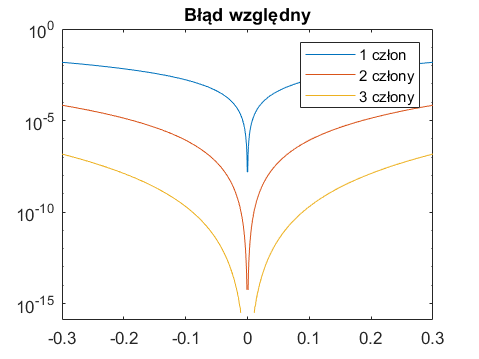


figure(2)
semilogy(x,relativeError1);
hold on ;
semilogy(x,relativeError2);
hold on ;
semilogy(x,relativeError3);
hold off ;
title('Błąd względny');
legend({'1 człon', '2 człony', '3 człony'})

Im większy rząd przybliżenia tym mniejszy błąd, zarówno wzlędny i bezwzględny

**1.5**. Dla poniższych układów równań wyznaczyć wskaźniki uwarunkowania korzystając z różnych norm macierzowych (funkcje `norm` lub `cond`). Podane układy rozwiązać metodą eliminacji Gaussa (napisać własny skrypt MojGauss.m) i porównać z rozwiązaniem dokładnym (zwróciź uwagę na przyczyny ewentualnych rozbieżności):

a)

    x + 2y = 10

    1.1x + 2y = 10.4

b)

    2x + 5.999999y = 8.000001

    2x + 6y = 8

c)

    5x + 3y + 4z = 18

    3x + z = 7

    6x + 3y + 6z = 27

Podpunkt a

%macierzowy zapis równań
A=[1,2; 1.1,2];
x=[10;10.4];
%metoda Gaussa

%wskaźniki ukierunkowania normy
cond1 = cond(A,1);
cond2 = cond(A,2);
condinf = cond(A,inf);
disp("Wskażnik uwarunkowania normy 1 to:"); disp(cond1) ;

Wskażnik uwarunkowania normy 1 to:
   62.0000



disp("Wskaźnik uwarunkowania normy 2 to:"); disp(cond2);

Wskaźnik uwarunkowania normy 2 to:
   51.0304



disp("Wskaźnik uwarunkowania normy nieskończoność to:"); disp(condinf);

Wskaźnik uwarunkowania normy nieskończoność to:
   62.0000




%rozwiązanie dokładne
result=A\x

result =     4.0000
    3.0000


%metoda Gaussa
gauss=MojGauss(A,x)

gauss =     4.0000
    3.0000


Podpunkt b

%macierzowy zapis równań
A=[2,5.999999; 2,6];
x=[8.000001;8];
%metoda Gaussa

%wskaźniki ukierunkowania normy
cond1 = cond(A,1);
cond2 = cond(A,2);
condinf = cond(A,inf);
disp("Wskażnik uwarunkowania normy 1 to:"); disp(cond1) ;

Wskażnik uwarunkowania normy 1 to:
   4.8000e+07



disp("Wskaźnik uwarunkowania normy 2 to:"); disp(cond2);

Wskaźnik uwarunkowania normy 2 to:
   4.0000e+07



disp("Wskaźnik uwarunkowania normy nieskończoność to:"); disp(condinf);

Wskaźnik uwarunkowania normy nieskończoność to:
   4.8000e+07




%rozwiązanie dokładne
result=A\x

result =     7.0000
   -1.0000


%metoda Gaussa
gauss=MojGauss(A,x)

gauss =     7.0000
   -1.0000


Podpunkt c

%macierzowy zapis równań
A=[5,3,4; 3,0,1;6,3,6];
x=[18;7;27];
%metoda Gaussa

%wskaźniki ukierunkowania normy
cond1 = cond(A,1);
cond2 = cond(A,2);
condinf = cond(A,inf);
disp("Wskażnik uwarunkowania normy 1 to:"); disp(cond1) ;

Wskażnik uwarunkowania normy 1 to:
   22.4000



disp("Wskaźnik uwarunkowania normy 2 to:"); disp(cond2);

Wskaźnik uwarunkowania normy 2 to:
   15.0124



disp("Wskaźnik uwarunkowania normy nieskończoność to:"); disp(condinf);

Wskaźnik uwarunkowania normy nieskończoność to:
    25




%rozwiązanie dokładne
result=A\x

result =      1
    -1
     4


%metoda Gaussa
gauss=MojGauss(A,x)

gauss =     1.0000
   -1.0000
    4.0000


**1.6**. Napisać prosty skrypt, sprawdzający czy dana macierz jest dodatnio określona. Następnie pokazać, że macierz A jest dodatnio określona i rozwiązać układ liniowych równań Ax = b metodą Choleskiego-Banachiewicza:

A = [4 8 −4

      8 17 −1

     −4 −1 57]

b =[ −12

      −17

       65]

A = [4 8 -4; 8 17 -1; -4 -1 57];
b = [-12; -17; 65];

% Sprawdzenie, czy A jest dodatnio określona i faktoryzacja
R = chol(A);
if isempty(R) || any(diag(R) <= 0)
    disp('Macierz nie jest dodatnio określona');
    return;
else 
    disp('Macierz jest dodanio określona')
end

Macierz jest dodanio określona



% rozwiązanie metodą Choleskiego-Banachiewicza
x = R\(R'\b)

x =     -2
     0
     1



% Wyświetlenie wyników
disp('Rozwiązanie układu równań:');

Rozwiązanie układu równań:


disp(x);

    -2
     0
     1



**1.7**. Rozwiązać układ równań metodą macierzy ortogonalnych

x − y = −1

2x + y = 1

x + 2y + z = 2

A = [1, -1, 0; 2, 1, 0; 1, 2, 1];
b = [-1, 1, 2]';
%faktoryzacja macierzy A
[Q,R] = qr(A);
%rozwiązanie układu równań
x = R^-1 * Q' * b;
disp("Rozwiązanie metodą QR:"); 

Rozwiązanie metodą QR:


disp(x);

    0.0000
    1.0000
    0.0000



**1.8**. Za pomocą metody iteracyjnej Jacobiego oraz metody iteracyjnej Gaussa Seidela (napisać własne skrypty MojJacobi.m i MojGaussSeidel.m) rozwiązać następujące równania (sprawdzić za każdym razem czy metoda będzie zbieżna):

a)

4x − y + z = 7

4x − 8y + z = −21

−2x + y + 5z = 15

b)

−2x + y + 5z = 15

4x − 8y + z = −21

4x − y + z = 7

Zbadać zależność szybkości zbieżności i poprawności rozwiązania od przybliżenia początkowego (przyjąć dokładności rozwiązania e = 10^−`2`, 10^−`4`, 10^−`10`). Sporządzić wykres relacji między błędem a liczbą iteracji oraz dokonać porównania skuteczności wykorzystywanych metod.

Podpunkt a


A = [4,-1,1;4,-8,1;-2,1,5];
b = [7;-21;15];
x0=[0;0;0]

x0 =      0
     0
     0


eps1=10^-2;
eps2=10^-4;
eps3=10^-10;
%badanie zbieżności
% Warunek wystarczający zbieżności dla metody Jacobiego
krytJacobi = all(2 * abs(diag(A)) > sum(abs(A), 2))

krytJacobi = logical
   1



% Warunek wystarczający zbieżności dla metody Gaussa-Seidela
krytGauss = all(2 * abs(diag(A)) > sum(abs(tril(A)), 2))

krytGauss = logical
   1


jacobi1 =     1.9871
    3.9953
    3.0066


iteration1 = 6

jacobi2 =     1.9995
    3.9998
    3.0002


iteration2 = 9

jacobi3 =     2.0000
    4.0000
    3.0000


iteration3 = 23

error =     0.1250    0.3438         0
    0.1719    0.0312    0.0583
    0.0375    0.0375    0.0375
    0.0047    0.0129         0
    0.0064    0.0012    0.0022
    0.0014    0.0014    0.0014
    0.0002    0.0005         0
    0.0002    0.0000    0.0001
    0.0001    0.0001    0.0001
    0.0000    0.0000         0


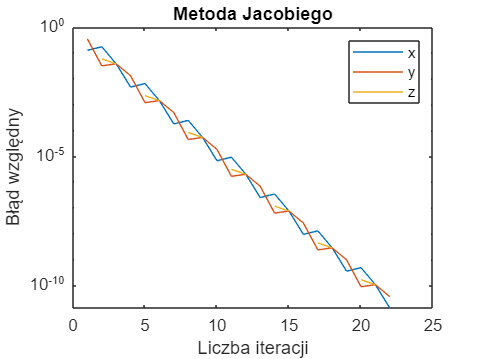

if(krytJacobi)
    [jacobi1,iteration1,~]=MojJacobi(A,b,x0,eps1)
    [jacobi2,iteration2,~]=MojJacobi(A,b,x0,eps2)
    [jacobi3,iteration3,error]=MojJacobi(A,b,x0,eps3)
    % Wykres dla metody Jacobiego
    figure(1)
    semilogy(error);
    title('Metoda Jacobiego')
    legend({'x','y','z'})
    xlabel('Liczba iteracji')
    ylabel('Błąd względny')
elseif(krytJacobi==0)
    disp('Metoda Jacobiego nie jest zbieżna')
end

gauss1 =     1.9931
    3.9736
    3.0012


iter1 = 4

gauss2 =     2.0000
    3.9999
    3.0001


iter2 = 7

gauss3 =     2.0000
    4.0000
    3.0000


iter3 = 15

error =     0.1250    0.2500         0
    0.0266    0.0281    0.0333
    0.0035    0.0066    0.0004
    0.0007    0.0008    0.0008
    0.0001    0.0002    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


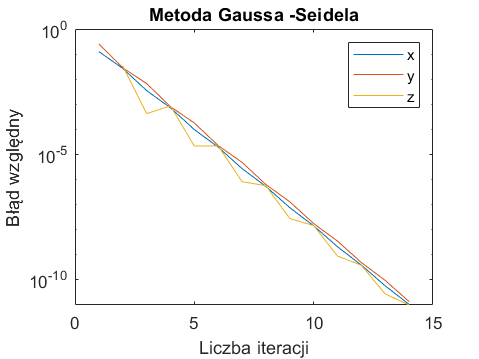


if(krytGauss)
    [gauss1,iter1,~]=MojGaussSeidel(A,b,x0,eps1)
    [gauss2,iter2,~]=MojGaussSeidel(A,b,x0,eps2)
    [gauss3,iter3,error]=MojGaussSeidel(A,b,x0,eps3)
    % Wykres dla metody Gaussa-Seidela
    figure(2)
    semilogy(error);
    title('Metoda Gaussa -Seidela')
    legend({'x','y','z'})
    xlabel('Liczba iteracji')
    ylabel('Błąd względny')
elseif(krytGauss==0)
    disp('Metoda Gaussa-Seidela nie jest zbieżna');
end

Wniosek - metoda Gaussa-Seidela jest szybsza

Podpunkt b


A = [-2,1,5;4,-8,1;4,-1,1];
b = [15,-21,7];
x0=[0;0;0]

x0 =      0
     0
     0


eps1=10^-2;
eps2=10^-4;
eps3=10^-10;
%badanie zbieżności
% Warunek wystarczający zbieżności dla metody Jacobiego
krytJacobi = all(2 * abs(diag(A)) > sum(abs(A), 2))

krytJacobi = logical
   0



% Warunek wystarczający zbieżności dla metody Gaussa-Seidela
krytGauss = all(2 * abs(diag(A)) > sum(abs(tril(A)), 2))

krytGauss = logical
   0


if(krytJacobi)
    [jacobi1,iteration1,~]=MojJacobi(A,b,x0,eps1)
    [jacobi2,iteration2,~]=MojJacobi(A,b,x0,eps2)
    [jacobi3,iteration3,error]=MojJacobi(A,b,x0,eps3)
    % Wykres dla metody Jacobiego
    figure(1)
    semilogy(error);
    title('Metoda Jacobiego')
    legend({'x','y','z'})
    xlabel('Liczba iteracji')
    ylabel('Błąd względny')
elseif(krytJacobi==0)
    disp('Metoda Jacobiego nie jest zbieżna')
end

Metoda Jacobiego nie jest zbieżna



if(krytGauss)
    [gauss1,iter1,~]=MojGaussSeidel(A,b,x0,eps1)
    [gauss2,iter2,~]=MojGaussSeidel(A,b,x0,eps2)
    [gauss3,iter3,error]=MojGaussSeidel(A,b,x0,eps3)
    % Wykres dla metody Gaussa-Seidela
    figure(2)
    semilogy(error);
    title('Metoda Gaussa -Seidela')
    legend({'x','y','z'})
    xlabel('Liczba iteracji')
    ylabel('Błąd względny')
elseif(krytGauss==0)
    disp('Metoda Gaussa-Seidela nie jest zbieżna');
end

Metoda Gaussa-Seidela nie jest zbieżna


**1.9.**Napisać funkcję `MojePolowienie.m` realizującą metodę połowienia (bisekcji), a następnie za jej pomocą rozwiązać równanie:

x = 1 + 0.3 cos(x)

Narysować wykres błędu bezwzględnego osiąganego w kolejnych krokach metody. Ile należy wykonać iteracji, aby metodą połowienia otrzymaną przybliżoną wartość pierwiastka z błędem nie przekraczającym 10^−`4`. Następnie zbadać zależność liczby potrzebnych iteracji od szerokości przedziału poszukiwań do osiągnięcia zadanej dokładności i zilustrować ją wykresem. Przyjąć maksymalny przedział poszukiwań równy [α − 10, α + 10], gdzie α jest pierwiastkiem równania. Następnie sukcesywnie zmniejszać przedział poszukiwań.


f = @(x) 1 + 0.3 * cos(x) - x;
eps=10^-4;
%wybrany przedział
a = 0;
b = pi/2;
% Wyznaczanie pierwiastka
[x, iteracje, error] = MojePolowienie(f, a, b, eps)

x = 1.1284

iteracje = 12

error =     0.4267    0.0633    0.1849    0.0615    0.0007    0.0304    0.0148    0.0071    0.0032    0.0012    0.0002    0.0003    0.0000


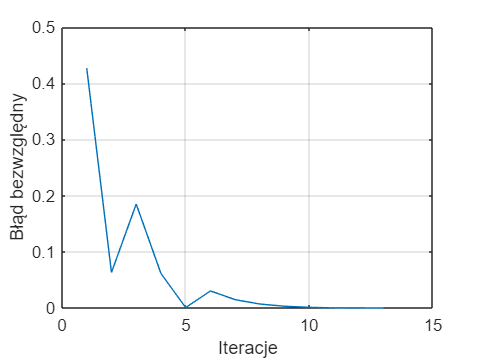


% Wykres błędu od iteracji
figure;
plot(1:length(error), error);
grid on;
xlabel('Iteracje');
ylabel('Błąd bezwzględny');

disp("Liczba iteracji do osiągnięcia dokładności:"+iteracje)

Liczba iteracji do osiągnięcia dokładności:12


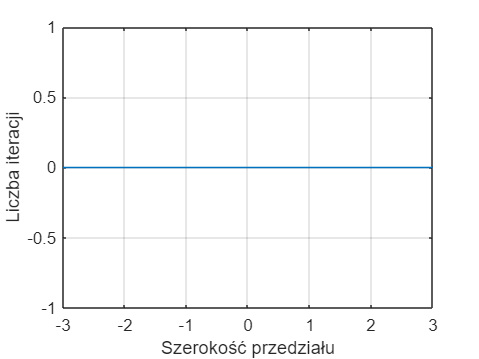

% Wykres iteracji w zależności od przedziału
przedzial = linspace(-3, 3, 100);
liczbaIteracji = zeros(size(przedzial));
%zawężanie przedziału 100 razy
for i = 1:length(przedzial)
    a = x - przedzial(i)/2;
    b = x + przedzial(i)/2;
    [x, liczbaIteracji(i),~] = MojePolowienie(f, a, b, eps);
end
figure;
plot(przedzial, liczbaIteracji);
grid on;
xlabel('Szerokość przedziału');
ylabel('Liczba iteracji');

Z nieznanych mi powodów podczas zawężania przedziału liczba iteracji funkcji MojePolowienie wynosi na całej odległości 0 tak jakby połowienie się nie odbywało

**1.10 **Napisać funkcje: `MojaRegulaFalsi.m` realizującą metodę reguły falsi, `MojaSieczna.m` realizującą metodę siecznych oraz `MojNewton.m` realizującą metodę Newtona. Następnie korzystając ze swoich funkcji wyznaczyć trzema metodami rozwiązania dla równania:

x = e^−x, x ∈ [0, 2].

Założyć dokładność rozwiązań na poziomie eps = 10^−`6`. Porównać skuteczność metod (wykres błędu w zależności od liczby iteracji).


f = @(x) x - exp(-x);
%pochodna funkcji
df = @(x) 1 + exp(-x);
%parametry
a=0;
b=2;
eps=10^(-6);

%metoda newtona
[newton,iteracjeN,errorN]=MojNewton(f,df,a,b,eps)

newton = 0.5671

iteracjeN = 3

errorN =     0.1065    0.0013    0.0000


%metoda reguły falsi
[falsi,iteracjeF,errorF]=MojaRegulaFalsi(f,a,b,eps)

falsi = 0.5671

iteracjeF = 7

errorF =     0.2007    0.0224    0.0025    0.0003    0.0000    0.0000    0.0000


%metoda siecznych
[sieczne,iteracjeS,errorS]=MojaSieczna(f,a,b,eps)

sieczne = 0.5671

iteracjeS = 5

errorS =     0.2007    0.0409    0.0009    0.0000    0.0000


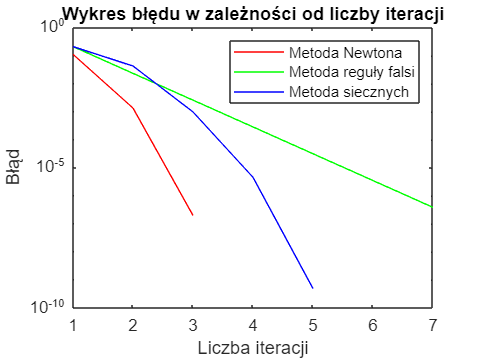


figure;
semilogy(1:length(errorN), errorN', 'r', 1:length(errorF), errorF', 'g', 1:length(errorS), errorS', 'b');
title('Wykres błędu w zależności od liczby iteracji');
xlabel('Liczba iteracji');
ylabel('Błąd');
legend('Metoda Newtona', 'Metoda reguły falsi', 'Metoda siecznych');

Metoda Newtona jest najszybsza i najdokładniejsza